**Initialize parameters**

clear; clc;
init

Initializing the environment
Selected Map: C:\Users\yekin\MECA_BOUN\2021-2022-1\MECA590\warehousemultirobot\simulation\data\EnvOccupancyMapDb\map100x100_4conveyors_5chargers.mat


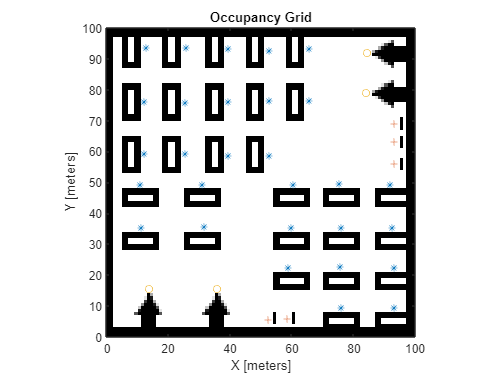

totalSimulationTime = 10000;
% pkg = [time, ldStNum, unLdShelfNum];
numPkgs = 100;
pkgTime = sort(1 + (totalSimulationTime-1)* rand(numPkgs,1));
pkgLdStNum = floor(1 + (length(loadingStations(1,:))-1)* rand(numPkgs,1));
pkgUnLdShelfNum = floor(1 + (length(shelvesLocations(1,:))-1)* rand(numPkgs,1));

packages = [pkgTime';pkgLdStNum';pkgUnLdShelfNum'];
currentPkgList = [];
deliveredPkgs = [];

vslz = true;
if vslz
    show(map); hold on; 
    scatter(shelvesLocations(1,:),shelvesLocations(2,:), '*');
    scatter(chargingStations(1,:),chargingStations(2,:), '+');
    scatter(loadingStations(1,:),loadingStations(2,:), 'o');
end

**Environment Interface**

mdl = "warehousemultirobot_main_m2020a";
open_system(mdl);
Tfinal = totalSimulationTime;
sampleTime = 0.1;

agentBlks = [mdl + "/Agents/RLAgent1", ...
             mdl + "/Agents/RLAgent2", ...
             mdl + "/Agents/RLAgent3", ...
             mdl + "/Agents/RLAgent4", ...
             mdl + "/Agents/RLAgent5"];

% [x,y,theta,charge,hasPkg,Px,Py,Ptheta,ldSt1Pkgs,[ldSt1Poses],ldSt2Pkgs,[ldSt2Poses],[lidarRanges]]
obsInfo = rlNumericSpec([mObsParams.observationsLength 1]);
obsInfo.Name = "Robot Observations"

obsInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: "Robot Observations"
    Description: [0×0 string]
      Dimension: [25 1]
       DataType: "double"


%numObservations = obsInfo.Dimension(1)


numActions = 2;
actInfo = rlNumericSpec([numActions 1],...
    "LowerLimit",-1,...
    "UpperLimit",1);
actInfo.Name = "Robot Speeds"

actInfo =   rlNumericSpec with properties:

     LowerLimit: -1
     UpperLimit: 1
           Name: "Robot Speeds"
    Description: [0×0 string]
      Dimension: [2 1]
       DataType: "double"



obsInfos = {obsInfo,obsInfo,obsInfo,obsInfo,obsInfo};
actInfos = {actInfo,actInfo,actInfo,actInfo,actInfo};

env = rlSimulinkEnv(mdl,agentBlks,obsInfos,actInfos);

**Create Agents (rlPPOAgent)**

[https://www.mathworks.com/help/reinforcement-learning/ug/ppo-agents.html](https://www.mathworks.com/help/reinforcement-learning/ug/ppo-agents.html)


% Reset the random seed to improve reproducibility
rng(0)

% Critic networks
criticNetwork = [...
    featureInputLayer(obsInfo.Dimension(1),'Normalization','none','Name','observation')
    fullyConnectedLayer(128,'Name','CriticFC1','WeightsInitializer','he')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(64,'Name','CriticFC2','WeightsInitializer','he')
    reluLayer('Name','CriticRelu2')
    fullyConnectedLayer(32,'Name','CriticFC3','WeightsInitializer','he')
    reluLayer('Name','CriticRelu3')
    fullyConnectedLayer(1,'Name','CriticOutput')];

% Critic representations
criticOpts = rlRepresentationOptions('LearnRate',1e-4);
critic1 = rlValueRepresentation(criticNetwork,obsInfo,'Observation',{'observation'},criticOpts);
critic2 = rlValueRepresentation(criticNetwork,obsInfo,'Observation',{'observation'},criticOpts);
critic3 = rlValueRepresentation(criticNetwork,obsInfo,'Observation',{'observation'},criticOpts);
critic4 = rlValueRepresentation(criticNetwork,obsInfo,'Observation',{'observation'},criticOpts);
critic5 = rlValueRepresentation(criticNetwork,obsInfo,'Observation',{'observation'},criticOpts);

% Actor networks
actorNetwork = [...
    featureInputLayer(obsInfo.Dimension(1),'Normalization','none','Name','observation')
    fullyConnectedLayer(128,'Name','ActorFC1','WeightsInitializer','he')
    reluLayer('Name','ActorRelu1')
    fullyConnectedLayer(64,'Name','ActorFC2','WeightsInitializer','he')
    reluLayer('Name','ActorRelu2')
    fullyConnectedLayer(32,'Name','ActorFC3','WeightsInitializer','he')
    reluLayer('Name','ActorRelu3')
    fullyConnectedLayer(4,'Name','Action')
    softmaxLayer('Name','SM')];

% Actor representations
actorOpts = rlRepresentationOptions('LearnRate',1e-4);
actor1 = rlStochasticActorRepresentation(actorNetwork,obsInfo,actInfo,...
    'Observation',{'observation'},actorOpts);
actor2 = rlStochasticActorRepresentation(actorNetwork,obsInfo,actInfo,...
    'Observation',{'observation'},actorOpts);
actor3 = rlStochasticActorRepresentation(actorNetwork,obsInfo,actInfo,...
    'Observation',{'observation'},actorOpts);
actor4 = rlStochasticActorRepresentation(actorNetwork,obsInfo,actInfo,...
    'Observation',{'observation'},actorOpts);
actor5 = rlStochasticActorRepresentation(actorNetwork,obsInfo,actInfo,...
    'Observation',{'observation'},actorOpts);

agentOptions = rlPPOAgentOptions(...
    'ExperienceHorizon',256,...
    'ClipFactor',0.125,...
    'EntropyLossWeight',0.001,...
    'MiniBatchSize',64,...
    'NumEpoch',3,...
    'AdvantageEstimateMethod','gae',...
    'GAEFactor',0.95,...
    'SampleTime',sampleTime,...
    'DiscountFactor',0.9995);

agentObj1 = rlPPOAgent(actor1,critic1,agentOptions);
agentObj2 = rlPPOAgent(actor2,critic2,agentOptions);
agentObj3 = rlPPOAgent(actor3,critic3,agentOptions);
agentObj4 = rlPPOAgent(actor4,critic4,agentOptions);
agentObj5 = rlPPOAgent(actor5,critic5,agentOptions);

agentsNew = [agentObj1, agentObj2, agentObj3, agentObj4, agentObj5];

**Train Agents**

maxEpisodes = 1000;
maxSteps = 5e3;
trainOpts = rlTrainingOptions(...
    'MaxEpisodes',maxEpisodes,...
    'MaxStepsPerEpisode',maxSteps,...
    'ScoreAveragingWindowLength',100,...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',-10);

agents = agentsNew;
doTraining = false;
open_system(mdl);
if doTraining
    stats = train(agents,env,trainOpts)
    save(satrcat("data\trained_agents_", datetime(now,'ConvertFrom','datenum')), agents)
else
    cd .\data\
    [file,path] = uigetfile('*.mat', "Select Environment Occupancy Map");
    cd ..\
    if isequal(file,0)
        disp('User selected Cancel');
    else
        disp(['Selected Map: ', fullfile(path,file)]);
        agents = load(fullfile(path,file));
        %show(map)
        %title("Shows Selected Map For Visualization. Close It")
    end
end

User selected Cancel


**Simulate Agents**

maxSteps = 5e3;
simOptions = rlSimulationOptions('MaxSteps',maxSteps,'StopOnError','on');
exp = sim(env,agents,simOptions);

Error using rl.env.AbstractEnv/simWithPolicy (line 83)
Unable to simulate model 'warehousemultirobot_main_m2020a' with the agent 'agentObj1, agentObj2, agentObj3, agentObj4, agentObj5'.

Error in rl.env.AbstractEnv/sim (line 176)
            [experiencesCell,simInfo] = simWithPolicy(env,policies,opts);

Caused by:
    Error using 